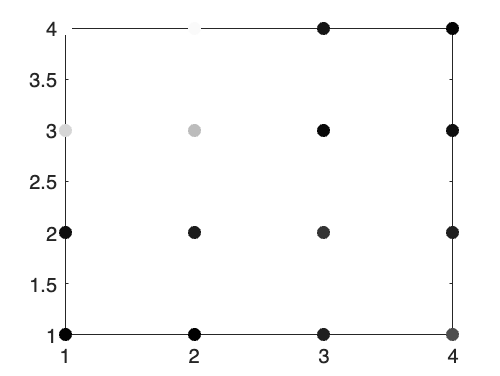

% Define a 4X4 image // small numbers are dark, large numbers are white
A = [2, 7, 84, 100; 
    1, 12, 74, 98;
    13, 21, 4, 9;
    31, 13, 7, 3];
c = gray(100);
figure
[n,m] = size(A);
figure
for i = 1:n
    for j = 1:m
        plot(i,j, 'o', 'Color', c(A(i,j),:), MarkerFaceColor=c(A(i,j),:))
        hold on
    end
end
hold off

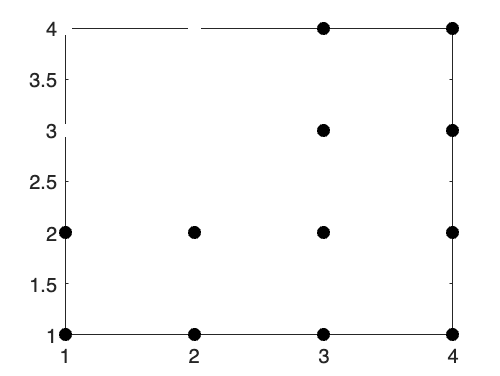

% Define labels
L = [1, 2]; % 1 - white, 2 - black
% Define seeds
S = [2,3,1; 4, 3, 2; 4, 1, 2; 1, 4, 1];
T = 150; % Number of steps
LD = zeros(n,m, numel(L));  % initalize limiting distribution

W = sparse(calculate_weights(A,150));
H = construct_hamiltonian(W, 0.1);
% U = construct_operator(H);

for i = 1:numel(L)
    subset = seeds_subset(S,L(i));
    subset_length = size(subset,1);
    A_sub = zeros(numel(A),1);
    for p = 1:subset_length
        A_sub(subset(p,2) + m*(subset(p,1)-1)) = A(subset(p,1), subset(p,2));
    end
    state = 1/subset_length * A_sub;
    D = zeros(16,T);
    for t = 1:T
        state = update_state(-1i,H,state);
        D(:,t) = retrieve_position(state);
    end
    LD(:,:,i) = reshape(1/T * sum(D,2),4,4)';
end
B = zeros(n,m);
b = [100, 1];
figure
for i = 1:m
    for j = 1:n
        k = find_seed(LD,i,j);
        B(i,j) = k;
        plot(i,j, 'o', "Color", c(b(B(i,j)),:), MarkerFaceColor=c(b(B(i,j)),:))
        hold on
    end
end
hold off